ImageRegistrationUsingNormalizedCrossCorrelation

Ref to:[https://ww2.mathworks.cn/help/images/registering-an-image-using-normalized-cross-correlation.html](https://ww2.mathworks.cn/help/images/registering-an-image-using-normalized-cross-correlation.html)

Shuai Yang 2021.06.30

% uiopen('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\CyOFP-10001.tif',1)
% % uiopen('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\CyOFP-10002.tif',1)
% CyOFP_10001 = imread('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\CyOFP-10001.tif');
% CyOFP_10002 = imread('E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\CyOFP-10002.tif');
fixed = imageCyOFP00002;
moving = imageCyOFP00003;

Calculate the normalized cross-correlation and display it as a surface plot. The peak of the cross-correlation matrix occurs where the sub_images are best correlated. normxcorr2 only works on grayscale images, so we pass it the red plane of each sub image.

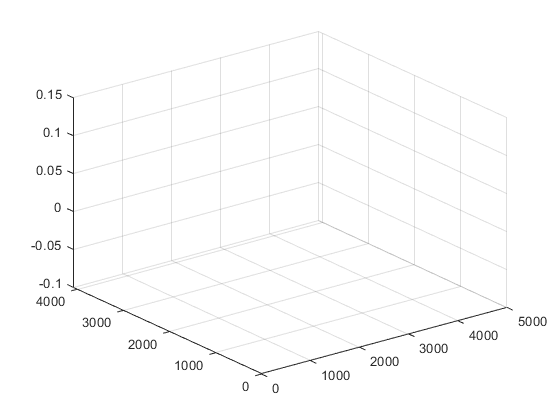


c = normxcorr2(fixed,moving);
figure, surf(c), shading flat

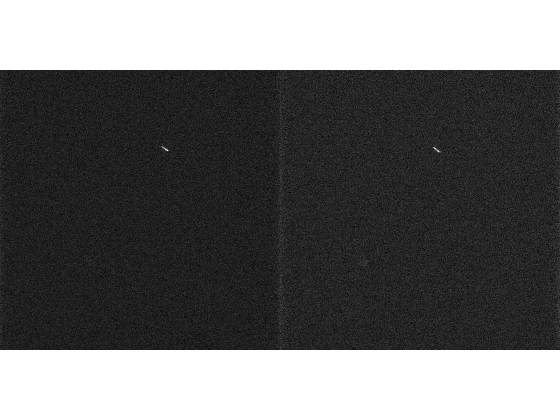


[ypeak,xpeak] = find(c == max(c(:)));

yShift = size(fixed,1) - ypeak;
xShift = size(fixed,2) - xpeak;

movingReg = imtranslate(moving,[xShift yShift],'FillValues',0);
imshowpair(fixed,movingReg,'montage');

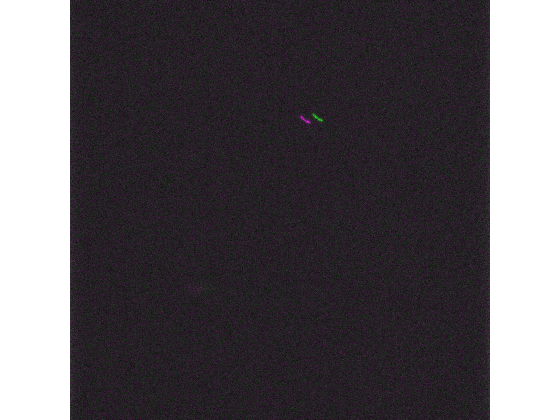

imshowpair(fixed,movingReg,'falsecolor');


% [max_c, imax] = max(abs(c(:)));
% [ypeak, xpeak] = ind2sub(size(c),imax(1));
% corr_offset = [(size(moving,2)-xpeak)
%                (size(moving,1)-ypeak)];
% x_offset = corr_offset(1);
% y_offset = corr_offset(2);

batch xy shift correction processing test

% tic;
% 
% allChannels = {'BF1','PVD','Venus','sfGFP','mScarletI','CyOFP','TDsmURFP'};
% baseChannel = 'CyOFP';
% dirFile = 'E:\2020-09-10-tracking segmentation demo test ys\image Regrister align测试\align test2';
% % dirFile = 'F:\2020-06-11-CyOFP tracking test ys';
% fieldList = dir([dirFile,filesep,'field*']);
% 
% for iField = 1%:numel(fieldList)
%     dirField = [dirFile,filesep,fieldList(iField).name];
%     channelList = dir(dirField);
%     disp (fieldList(iField).name);
%     
%     
%     channelTF = false(size(allChannels));
%     for iChannel = 1:length(channelList)
%         
%         if(isequal(channelList(iChannel).name,'.')||...
%                 isequal(channelList(iChannel).name,'..')||...
%                 ~channelList(iChannel).isdir)
%             continue;
%         end
%         
%         [Lia,Locb] = ismember(channelList(iChannel).name,allChannels);
%         if Lia
%             channelTF(Locb) = true;
%         end
%         
%     end
%     existChannels = allChannels(channelTF);
%     % 以phase image 进行xy shift 矫正
%     if ismember(baseChannel,existChannels)
%         imList = dir([dirField,filesep,baseChannel,filesep,'*.tif']);
%         xyShift_Array = zeros(numel(imList)-1,2);
%         
%         priorImList = imList(1:end-1);
%         afterImList = imList(2:end);
%         
%         parfor iImage = 1:numel(priorImList)
%             priorIm = imread([dirField,filesep,baseChannel,filesep,priorImList(iImage).name]);
%             afterIm = imread([dirField,filesep,baseChannel,filesep,afterImList(iImage).name]);
%             
%             c = normxcorr2(priorIm,afterIm);
%             [ypeak,xpeak] = find(c == max(c(:)));
%             yShift = size(priorIm,1) - ypeak;
%             xShift = size(priorIm,2) - xpeak;
%             
%             xyShift_Array(iImage,:) = [xShift,yShift];
%         end
%     end
%     cumShift_Array = cumsum(xyShift_Array,1);%Cumulative 累积的xy偏移量
% 
%     
%     dirNew = [dirField,filesep,baseChannel,'_NCC'];
%     if ~isfolder(dirNew)
%         mkdir(dirNew)
%     end
% 
%     parfor iImage = 1:numel(afterImList)
%         imIn = imread([dirField,filesep,baseChannel,filesep,afterImList(iImage).name]);
%         imOut = imtranslate( imIn, cumShift_Array(iImage,:),'FillValues', min(imIn(:)));
%         imwrite(imOut,[dirNew,filesep,afterImList(iImage).name]);
%     end
%     
% end
% toc;

